## Postprocessing outputs generated by gBAT

So you ran an analysis! Now you may be wondering how to change visualization settings or apply different thresholds to the gBAT outputs you are looking at. Let's go to an example output folder we've generated to see how to do this (also, check out our comprehensive manual for more information on gBAT usage).

[d,~,~] = fileparts(which('gBATGui.mlapp'));
if isempty(d)
    error('Uh oh! You do not have gBAT in your matlab path...please add before proceeding')
else
    cd([d filesep 'examplePostpro'])
end

First, you can always load up one of the automatically generated figures that gBAT has saved in case you want to zoom in, resize the figure, or if you can't find the associated png file. Below you are seeing the results of a linear correlation between age and grey matter volume in a couple of individuals (p < 0.05). You can tell the map is thresholded based on the '_VoxThresh' in the filename, followed by the p-value we used. By default, we use the viridis colormap so higher values will correspond to brighter yellow and darker green and blue to lower values. The limits of the colormap follow the p-value. 

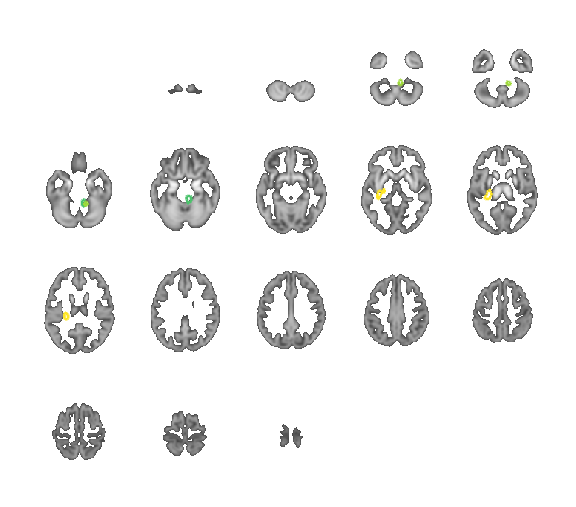

uiopen('Age_pearson_stat_VoxThresh0.05_0_0.42271.fig',1)

To recreate the default images we can use brainMontagerWithAtlas.m for gBat analyses that were regional (i.e., based on regions in an atlas), we can use brainMontagerWithAtlas.m like so:

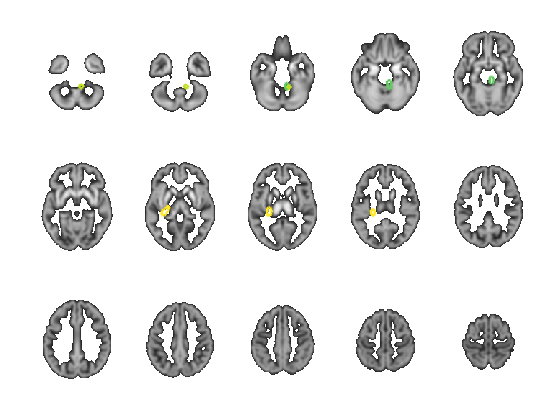

warning off;
[~,~,~,~,~] = brainMontagerWithAtlas('Age_pearson_stat_VoxThresh0.05.nii.gz','meanSubMap.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[20:5:90],1000,[0 0.4],'viridis',[],[1 1 1],false,1000,[],'gray',[],0.8,'ud',true,false,true,0.1,'both');

The first file input to brainMontager will be plotted as outlines on top of the brain (an overlay). The second file input will be the underlay, visualized without outlines. You can see some differences in the map we manually generated. Just to mix things up, we used the raw mean image of all the inputs that went into this analysis. To replicate the saved figure exactly, you can use meanSubMap_threshold_mask.nii.gz instead. The other difference is the slices we are plotting. I selected some randomly here, but gBAT tries to estimate this using data it has loaded in to get decent coverage of the whole brain. This is controlled by the third input argument.

Note, the rjhu.nii.gz nifti is the JHU atlas, but not in MNI152 space. We do provide all atlases in MNI152. 

You can create a colorbar to stitch together for a figure using the generateColorbarImage.m function in ./helpers. Here, we use the same settings as above. The first argument is the same colormap we used to generate our montage, the second is the same number of bins in the colormap, the third are the same limits, and the last argument determines whether we should invert the colormap, which is an option available in brainMontagerWithAtlas. Note, when you run this outside the live code, you shouldn't see two colormaps like below (just one will appear). 

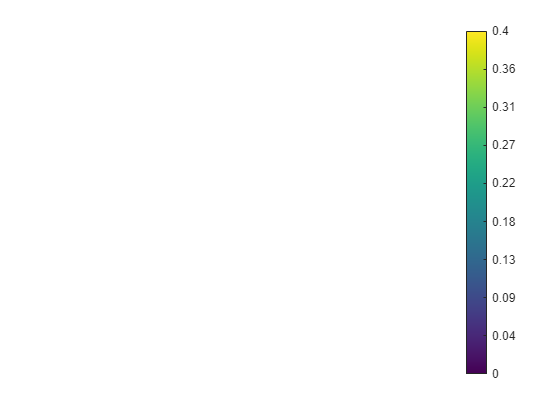

generateColorbarImage('viridis', 1000, [0 0.4],false)

The fourth input argument in brainMontagerWithAtlas determines the number of color bins in the overlay. This will be difficult to see changes in for our particular map, which has few regions, but you can see the effect this would have by generating a new colormap. There will be fewer colors.

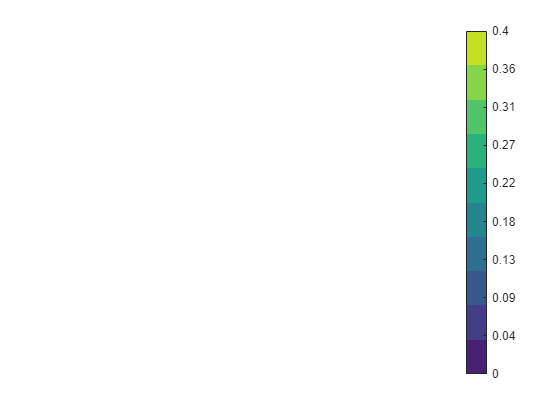

generateColorbarImage('viridis', 10, [0 0.4],false)

The 7th input to brainMontagerWithAtlas is the colormap. See the documentation for more options, but there are many available to you. Here's another option that we can use with the raw map to see more colors in the map. Note, this will take longer to run because there are more regions. We plot each region as a seperate map

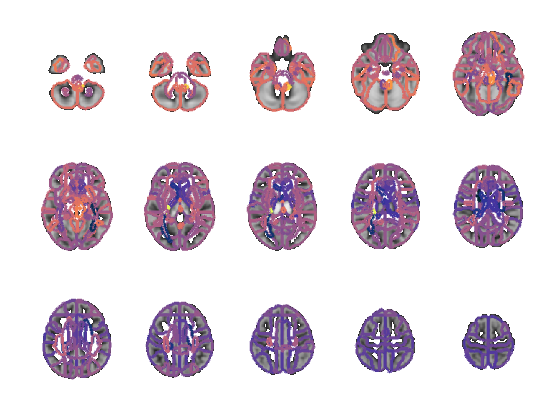

[~,~,~,~,~] = brainMontagerWithAtlas('Age_pearson_stat.nii.gz','meanSubMap.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[20:5:90],1000,[0 0.4],'thermal',[],[1 1 1],false,1000,[],'gray',[],0.8,'ud',true,false,true,0.1,'both');

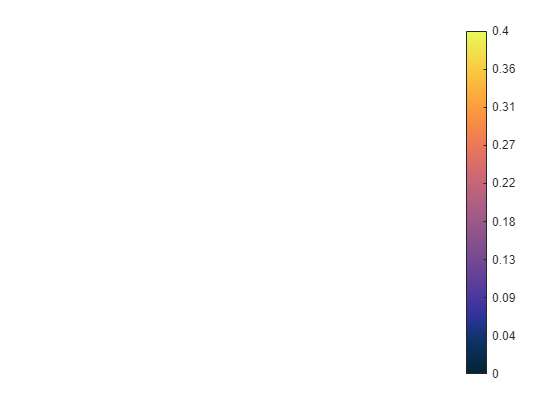

generateColorbarImage('thermal', 1000, [0 0.4],false)

The 8th input to brainMontagerWithAtlas is a threshold that you can apply to the values of the overlay being plotted. Let's say we want to threshold the map at 0.2 now, ignoring the p-value:

[~,~,~,~,~] = brainMontagerWithAtlas('Age_pearson_stat.nii.gz','meanSubMap.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[20:5:90],1000,[0 0.4],'thermal',[0 0.3],[1 1 1],false,1000,[],'gray',0.3,0.8,'ud',true,false,true,0.1,'both');

You don't have to have the overlay show outlines of the ROIs. The 17th input to brainMontagerWithAtlas determines whether we will create outlines for ROIs in the overlay--just set this to false. Here I have also decreased the opacity of the underlay so that you can more clearly see the regions being plotted

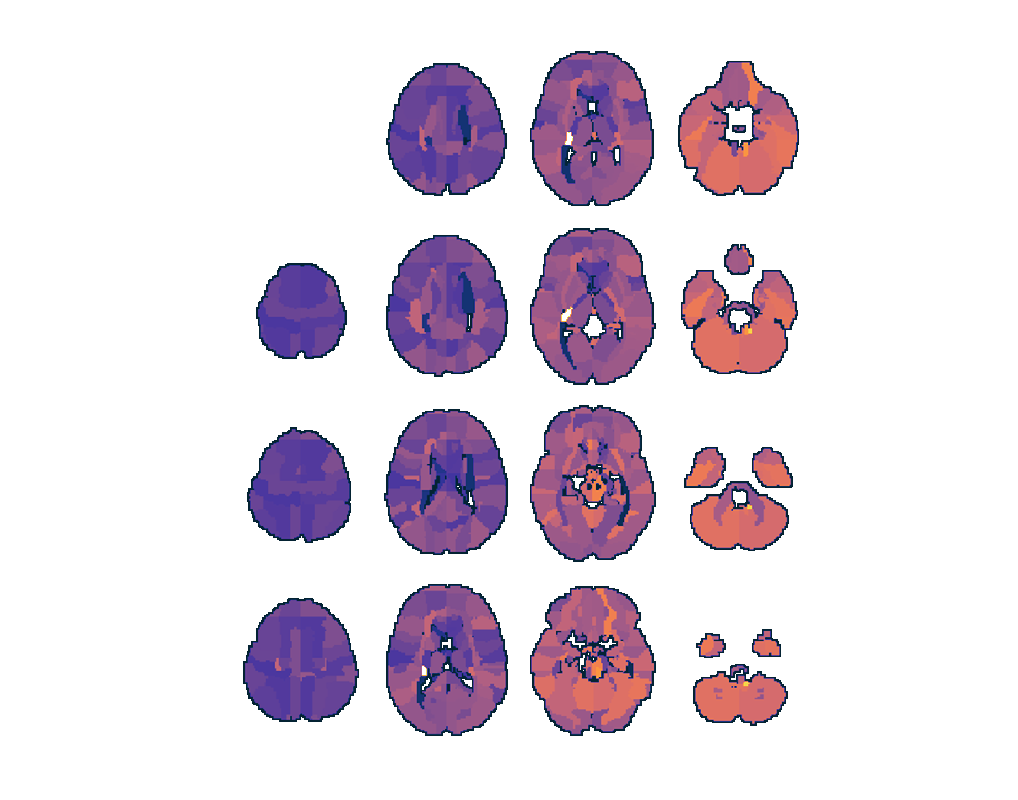

[~,~,~,~,~] = brainMontagerWithAtlas('Age_pearson_stat.nii.gz','meanSubMap.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[20:5:90],1000,[0 0.4],'thermal',[],[1 1 1],false,1000,[],'gray',[],0,'ud',false,false,true,0.1,'both');

If you are interested in converting regional results in volume space to surface space, you can either use the postprocessing GUI within gBat, or the atlasVol2Surf command likeso: 

atlasVol2Surf('Age_pearson_stat.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[d filesep 'atlases' filesep 'JHU' filese 'jhu_reg_to_MNI152_noWM_CombinedClusters_FSSpace_LH.nii.gz'],[d filesep 'atlases' filesep 'JHU' filese 'jhu_reg_to_MNI152_noWM_CombinedClusters_FSSpace_LH.nii.gz']);

To FDR correct raw maps (or Bonferroni), use the gBAT postprocessing GUI. However, you can also do some FDR correction using postpro.m. The difference is that postpro.m only provides voxelwise correction. For regional analyses, please use the GUI, which will correct for comparisons only among the ROIs. Postpro will automatically generate lots of files just as running gBAT would. It generates new montage figures and allows you to apply a different threshold to your map. You should also define the limits and supply a few other arguments. See pospro.m. Here is an example where we set the p-value to 0.1:

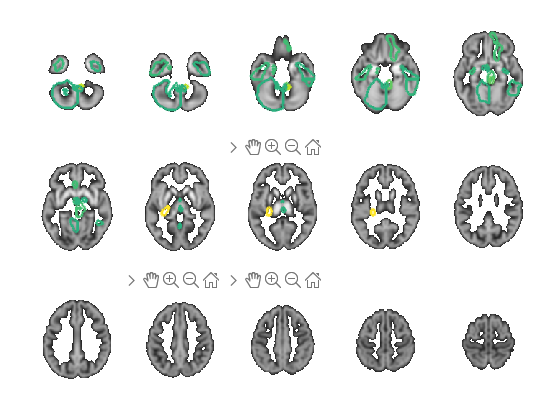

nameOfFile = postpro('Age_pearson_stat.nii.gz','Age_pearson_pval.nii.gz',0.1,'pos','meanSubMap.nii.gz',0.1,'pos',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[],false);

And we can create a montage with our new thresholded map. There is also a way to generate these automatically (see posptro.m)

[~,~,~,~,~] = brainMontagerWithAtlas(nameOfFile,'meanSubMap.nii.gz',[d filesep 'atlases' filesep 'JHU' filesep 'rjhu.nii'],[20:5:90],1000,[0 0.4],'viridis',[],[1 1 1],false,1000,[],'gray',[],0.8,'ud',true,false,true,0.1,'both');

More examples forthcoming!